clear all
close all

addpath('../DSFO/');

Solve the Trace Ratio Optimization (TRO) problem, given by:


$$\text{arg}\max_X\frac{\text{tr}\left(X^TR_{\mathbf{yy}}X\right)}{\text{tr}\left(X^TR_{\mathbf{vv}}X\right)}\\
\text{s.t. } X^TX=I,$$


in a distributed context using the Distributed Signal Fusion Optimization (DSFO) framework. $R_{\mathbf{yy}}$ and $R_{\mathbf{vv}}$ are the correlation matrices of the multi-channel signals $\mathbf{y}$ and $\mathbf{v}$respectively, i.e., $R_{\mathbf{yy}}=\mathbb{E}[\mathbf{y}(t)\mathbf{y}^T(t)]$ and $R_{\mathbf{vv}}=\mathbb{E}[\mathbf{v}(t)\mathbf{v}^T(t)]$.

Let us first define the network. We take a randomly connected network with 30 nodes and 15 channels per node.

nbnodes=30;
nbsensors_vec=15*ones(nbnodes,1);
nbsensors=sum(nbsensors_vec);
adj=randi(2,nbnodes,nbnodes)-1;
graph_adj=triu(adj,1)+tril(adj',-1);

Next, we create the data using 

found at the end of this file. The number of time samples of the signals is 10000 and we choose the number of filters to be equal to 5, i.e., $X$ has 5 columns.

nbsamples=10000;
[Y,V]=create_data(nbsensors_vec,nbnodes,nbsamples);
Q=5;

The data are stored in 4 different cells, 

- One for the (stochastic) signals. In this example, the cell contains two elements, the signals $\mathbf{y}$ and $\mathbf{v}$. 

Y_cell=cell(2,1);
Y_cell{1}=Y;
Y_cell{2}=V;

- One for deterministic constant matrices. In this example, we do not have any.

B_cell={};

- One for quadratic terms. Here, we have only one, which is the identity matrix.

Gamma_cell{1}=eye(nbsensors);

- The final one for global constraint parameters, i.e., those that are not filtered using $X$. In this case, we do not have any.

Glob_Const_cell={};

We then create structures for the data, problem parameters and stopping criteria called 

respectively:

data=struct;
data.Y_cell=Y_cell;
data.B_cell={};
data.Gamma_cell=Gamma_cell;
data.Glob_Const_cell={};

prob_params=struct;
prob_params.nbsensors=nbsensors;
prob_params.Q=Q;
prob_params.nbnodes=nbnodes;
prob_params.nbsensors_vec=nbsensors_vec;
prob_params.nbsamples=nbsamples;
prob_params.graph_adj=graph_adj;

conv=struct;
conv.tol_f=-1;
conv.nbiter=200;

Then, an optimal filter $X^*$ solving the TRO problem is estimated using the centralized algorithm: 

Note that any sign change on the columns of $X^*$ is also a valid solution.

[X_star,f_star]=tro_solver(data,prob_params);
prob_params.X_star=X_star;
% Compute the distance to X^* if equal to 1 
prob_params.compare_opt=1;
% Show a dynamic plot if equal to 1
prob_params.plot_dynamic=0;

The distributed implementation is then called using the function 

 which takes as parameters the data, problem parameter and stopping criteria structures along with the functions 

which evaluates the TRO objective given a certain $X$, solves the centralized TRO problem and resolves the uniqueness ambiguity of the TRO, respectively.

[X_est,f_diff,norm_diff,norm_err]=dsfo(data,prob_params,...
        conv,@tro_eval,@tro_solver,@tro_resolve_uniqueness);

Let us plot the normalized error $\epsilon$ given by:

$\epsilon(X^i)=\frac{||X^i-X^*||_F^2}{||X^*||_F^2}$,

which is stored in

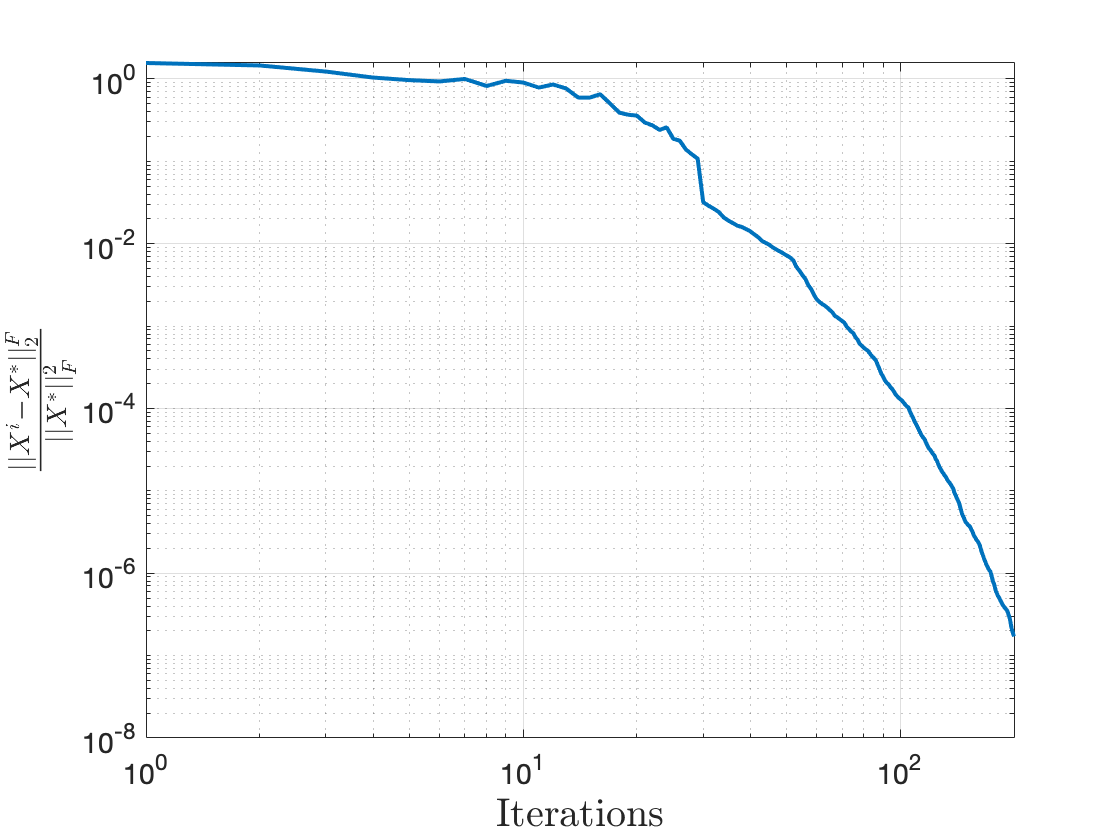

loglog([1:200],norm_err,'LineWidth',2)
ax=gca;
ax.FontSize=14;
xlim([1,inf])
ylim([1e-8,inf])
xlabel('Iterations','Interpreter','latex','Fontsize',20)
ylabel('$\frac{||X^{i}-X^*||_2^F}{||X^*||_F^2}$','Interpreter','latex','Fontsize',20)
grid on

The function we use to create the signals $\mathbf{y}$ and $\mathbf{v}$.

function [Y,V]=create_data(nbsensors_vec,nbnodes,nbsamples)
    noisepower=0.1; 
    signalvar=0.5;
    nbsources=5;
    latent_dim=10;

    rng('shuffle');
    d=randn(nbsamples,nbsources);
    d=sqrt(signalvar)./(sqrt(var(d))).*(d-ones(nbsamples,1)*mean(d));
    s=randn(nbsamples,latent_dim-nbsources);
    s=sqrt(signalvar)./(sqrt(var(s))).*(s-ones(nbsamples,1)*mean(s));

    for k=1:nbnodes
        Ainit{k}=rand(nbsources,nbsensors_vec(k))-0.5;
        Binit{k}=rand(latent_dim-nbsources,nbsensors_vec(k))-0.5;
        noise{k}=randn(nbsamples,nbsensors_vec(k)); 
        noise{k}=sqrt(noisepower)./sqrt(var(noise{k})).*(noise{k}-ones(nbsamples,1)*mean(noise{k}));
    end

    column_blk=0;

    Y_cell=cell(nbnodes,1);
    V_cell=cell(nbnodes,1);
    
    for k=1:nbnodes
        V_cell{k}=s*Binit{k}+noise{k};
        Y_cell{k}=d*Ainit{k}+V_cell{k};

        Y(1:nbsamples,column_blk+1:column_blk+nbsensors_vec(k))=Y_cell{k};
        V(1:nbsamples,column_blk+1:column_blk+nbsensors_vec(k))=V_cell{k};
        column_blk=column_blk+nbsensors_vec(k);
    end
    
    Y=Y';
    V=V';

end